# Unit Testing

The goal is to test the graphical App of the Parking Meter system.

## 1. Clean Session

Clear all remaining variables, figures and timers:

clear variables; close all; clc;
try
  stop(timerfind);
  delete(timerfind);
catch
  disp('No timers are running.');
end

No timers are running.


Add needed classes to the import list:

import matlab.unittest.TestRunner;
import matlab.unittest.TestSuite;
import matlab.unittest.plugins.TestReportPlugin;
import matlab.unittest.plugins.CodeCoveragePlugin;

## 2. Test Runner and Test Suite

Build test runner and test suite allowing to customize how the suite is run and which tests to run.

runner = TestRunner.withTextOutput;

Test report format:

reportName = 'Report';
reportType = 'pdf';
switch (reportType)
  case 'docx'
    reportPlugin = TestReportPlugin.producingDOCX([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'html'
    reportPlugin = TestReportPlugin.producingHTML([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'pdf'
    reportPlugin = TestReportPlugin.producingPDF([reportName '.' reportType],...
                                                 'IncludingPassingDiagnostics',true,...
                                                 'IncludingCommandWindowText',true);
  otherwise
    error('Unsupported file type for a report.');
end
runner.addPlugin(reportPlugin);

Coverage report:

coveragePlugin = CodeCoveragePlugin.forFile('..\Component\ParkingMeterGUI.mlapp');
runner.addPlugin(coveragePlugin);

Create the test suite from the defined test class

classSuite = TestSuite.fromClass(?TestApp);

## 3. Initialization

Preparing the parking meter system for the tests:

global UNIT_TESTING; %#ok<GVMIS> 
% Set to true if the MATLAB unit testing API is used, otherwise always false
UNIT_TESTING = true;
% Close any potential running instance of the low-level application
if (system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &') ~= 0)
  fprintf('No running instance of the low-level application has been detected.\n');
end

No running instance of the low-level application has been detected.


% Call the low-level MATLAB code of the application in a separate process
fprintf('Starting the low-level application instance...\n');

Starting the low-level application instance...


system('..\\Component\\UnitTesting\\ParkingMeterProject.exe&');

## 4. Run Tests

Running TestApp
. Processing the test case #1...


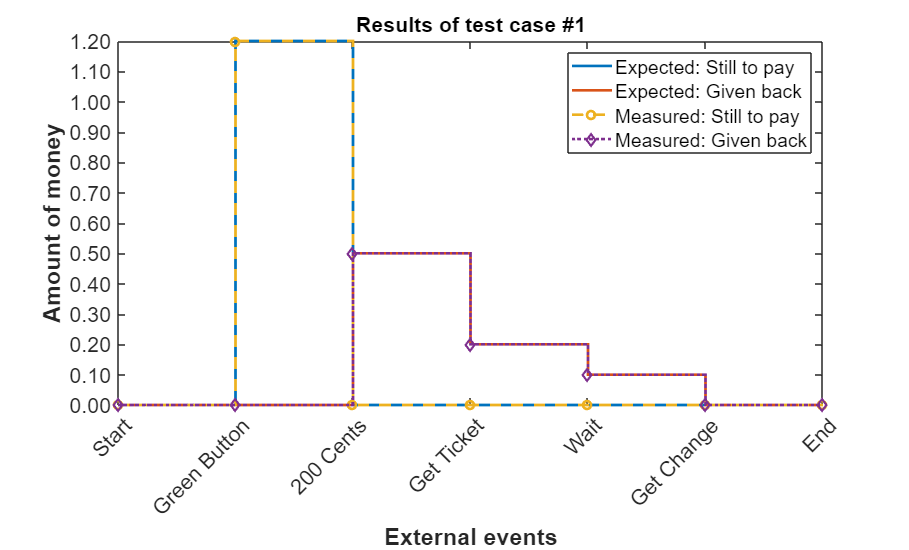


[Terse] Diagnostic logged (2022-06-30 16:32:03):
Figure saved to:
--> C:\Users\sdupertu\AppData\Local\Temp\56860478-3679-413d-8a0f-d88829ba8fc5\Figure_7f5779c9-666d-4707-b16f-249f3bb14c12.fig
--> C:\Users\sdupertu\AppData\Local\Temp\56860478-3679-413d-8a0f-d88829ba8fc5\Figure_7f5779c9-666d-4707-b16f-249f3bb14c12.png
. Processing the test case #2...


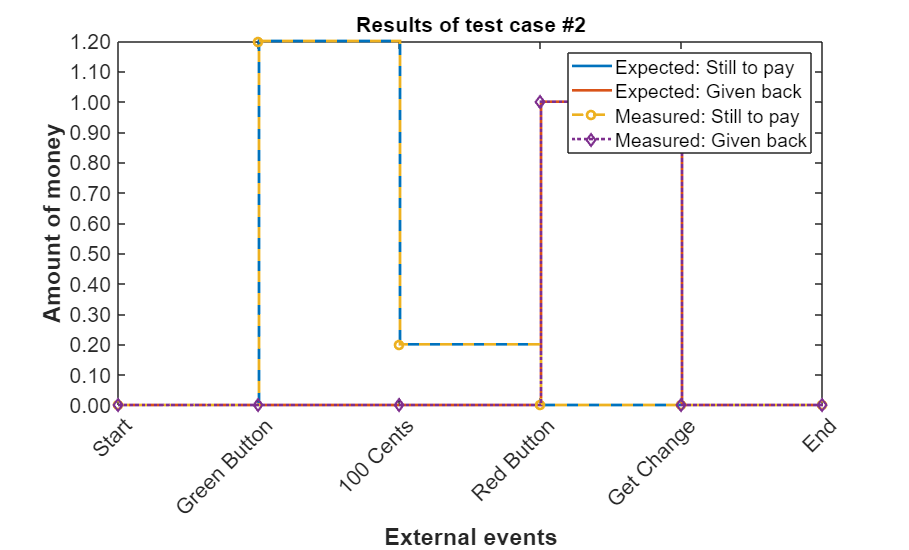


[Terse] Diagnostic logged (2022-06-30 16:32:21):
Figure saved to:
--> C:\Users\sdupertu\AppData\Local\Temp\56860478-3679-413d-8a0f-d88829ba8fc5\Figure_e6a62e70-908f-459d-91d5-8e0e80ee3790.fig
--> C:\Users\sdupertu\AppData\Local\Temp\56860478-3679-413d-8a0f-d88829ba8fc5\Figure_e6a62e70-908f-459d-91d5-8e0e80ee3790.png
. Processing the test case #3...


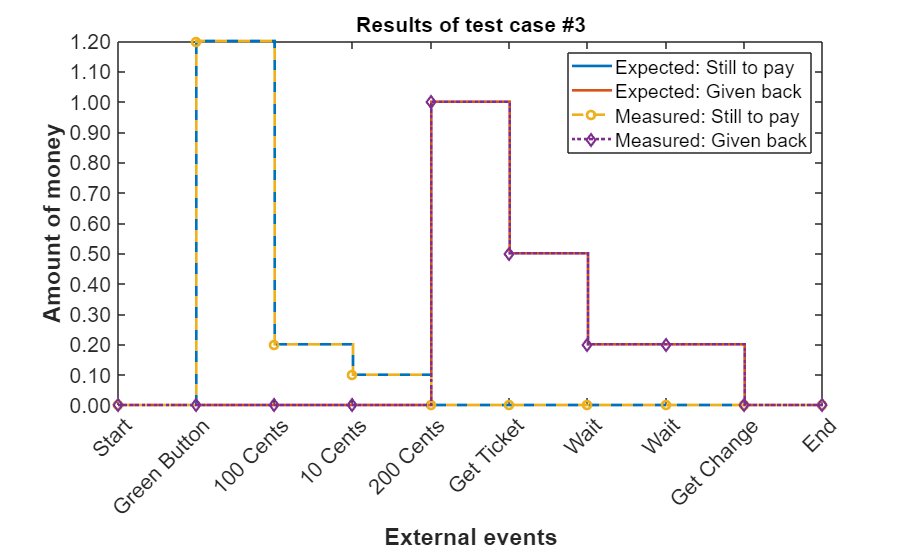


[Terse] Diagnostic logged (2022-06-30 16:32:43):
Figure saved to:
--> C:\Users\sdupertu\AppData\Local\Temp\56860478-3679-413d-8a0f-d88829ba8fc5\Figure_59d03155-c20b-49d4-8666-75ba6772b0af.fig
--> C:\Users\sdupertu\AppData\Local\Temp\56860478-3679-413d-8a0f-d88829ba8fc5\Figure_59d03155-c20b-49d4-8666-75ba6772b0af.png
. Processing the test case #4...


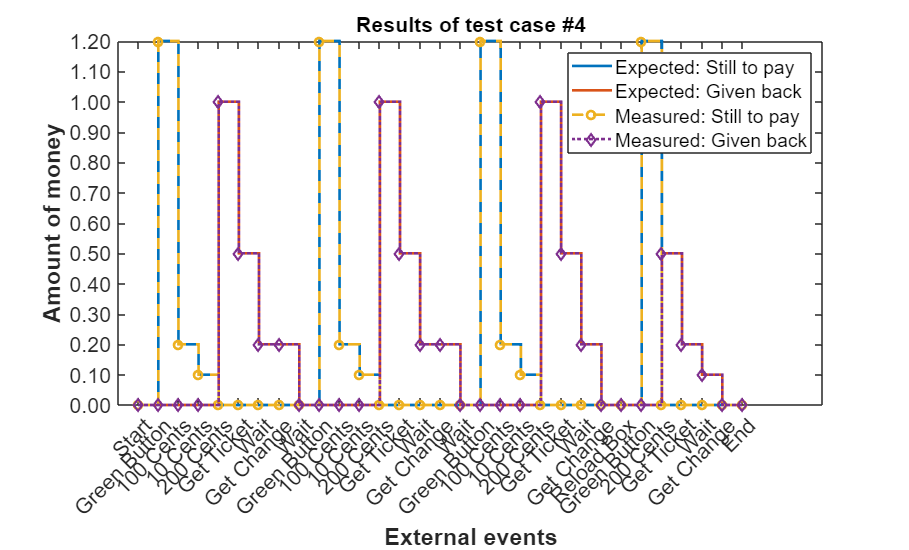


[Terse] Diagnostic logged (2022-06-30 16:33:46):
Figure saved to:
--> C:\Users\sdupertu\AppData\Local\Temp\56860478-3679-413d-8a0f-d88829ba8fc5\Figure_358ec421-9919-4db8-b57d-428a10b65560.fig
--> C:\Users\sdupertu\AppData\Local\Temp\56860478-3679-413d-8a0f-d88829ba8fc5\Figure_358ec421-9919-4db8-b57d-428a10b65560.png
.
Done TestApp
__________

Generating test report. Please wait.
    Preparing content for the test report.
    Adding content to the test report.
    Writing test report to file.
Test report has been saved to:
 C:\GitHub\C_Code_Integration\MATLAB\Work\Report.pdf
Code coverage report has been saved to:
 C:\Users\sdupertu\AppData\Local\Temp\tp934945d5_127f_4d83_afac_30b1d5f428ac\index.html


% Call the unit testing framework for automated testing
results = runner.run(classSuite);

% Close the running instance of the low-level application
system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &');

## 5. Results Summary

disp(results.table);

                            Name                            Passed    Failed    Incomplete    Duration      Details   
    ____________________________________________________    ______    ______    __________    ________    ____________

    {'TestApp/testCase_1_StraightTicketPurchase'       }    true      false       false        17.779     {1×1 struct}
    {'TestApp/testCase_2_CancelTicketPurchase'         }    true      false       false        17.522     {1×1 struct}
    {'TestApp/testCase_3_BiggestChangeOnTicketPurchase'}    true      false       false         21.93     {1×1 struct}
    {'TestApp/testCase_4_FullyEmptyAndReloadCashBox'   }    true      false       false        63.311     {1×1 struct}

